# Lid-driven Cavity

clear, close all, clc
set_demo_defaults

We discuss a simple model problem for the flow in the mantle beneath mid-ocean ridges. In the standard models of the thermal structure of the oceanic lithosphere the flow is assumed to be purely horizontal and with the plate velocity. We will solve the corresponding Stokes flow problem for a "corner flow" induced by the velocity of the overlying plate and the (assumed) symmetry condition beneath the ridge. We assume the corner flow is determined by the following Stokes flow problem:

$\nabla\cdot\left[\mu(\nabla \mathbf{v}+\nabla^\mathrm{T}\mathbf{v})\right] - \nabla p = 0
$   and     $\nabla\cdot\mathbf{v} = 0$      on       $x \in \left[0,\,1\right] \times y \in \left[0,\,1\right]$

with BC's: 

Top boundary: $v_x(x,y = 1) = 1$, $v_y(x,y=1) = 0$

Other boundaries: $\mathbf{v}\cdot\mathbf{n} = 0$, $\nabla\mathbf{v}\cdot\mathbf{n} = 0$

mu = 1;

%% Build staggered grids
Gridp.xmin = 0; Gridp.xmax = 1; Gridp.Nx = 50;
Gridp.ymin = 0; Gridp.ymax = 1; Gridp.Ny = 50;
Grid = build_stokes_grid(Gridp);

%% Build Stokes operators
[D,Edot,Dp,Gp,Z,I,M] = build_stokes_ops(Grid);
A = 2*mu*D*Edot; % 
L = [A, -Gp;...
     Dp, Z];
fs = spalloc(Grid.N,1,0);

%% Boundary conditions
BC.dof_dir = [Grid.dof_ymax_vt;...  % tangential velocity on the top
              Grid.dof_pene;...     % no penetration on all bnd's
              Grid.dof_pc];         % pressure constraint
          
BC.g       = [ones(Grid.p.Nx-1,1);...       % tangential velocity on the top
              zeros(Grid.N_pene,1);...      % no penetration on all bnd's
              0];                           % pressure constraint
[B,N,fn] = build_bnd(BC,Grid,I);

%% Solve for Stokes flow
u = solve_lbvp(L,fs+fn,B,BC.g,N);
v = u(1:Grid.p.Nf); p = u(Grid.p.Nf+1:end);
PSI = comp_streamfun(v,Grid.p);


## Visualizing the solution

### 1. Vector plot

The most obvious way is to plot the vector field as arrows. Matlab has a function called [quiver.m](https://www.mathworks.com/help/matlab/ref/quiver.html) for this purpose. However, this requires both velocity components in the same location. Hence we average both velocity component to the cell centers. Even once that is accomplished the plots are often not very informative. 

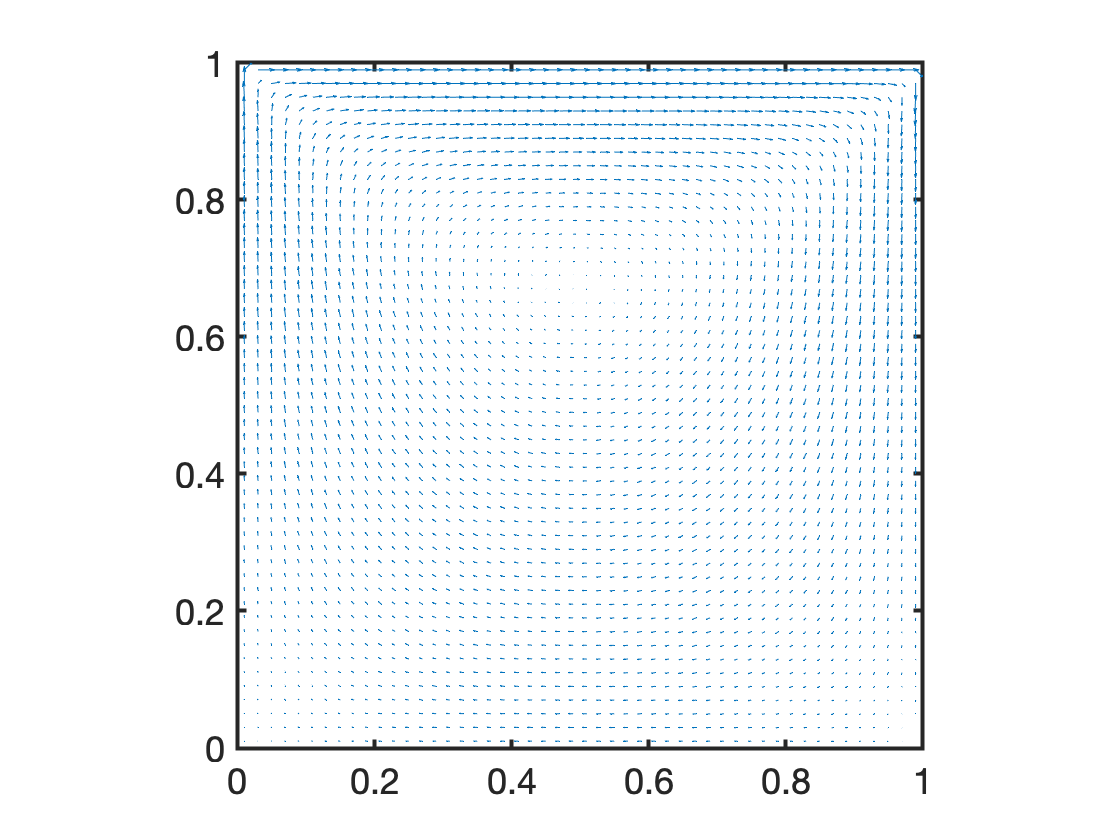

% Generate pressure and velocity grids
[Xc,Yc] = meshgrid(Grid.p.xc,Grid.p.yc);
[Xx,Yx] = meshgrid(Grid.x.xc,Grid.x.yc);
[Xy,Yy] = meshgrid(Grid.y.xc,Grid.y.yc);

% Extract and reshape the velocity vectors
vx = v(1:Grid.x.N);     VX = reshape(vx,Grid.x.Ny,Grid.x.Nx);
vy = v(Grid.x.N+1:end); VY = reshape(vy,Grid.y.Ny,Grid.y.Nx);

% Interpolate to cell centers
VXc = interp2(Xx,Yx,VX,Xc,Yc);
VYc = interp2(Xy,Yy,VY,Xc,Yc);

quiver(Xc,Yc,VXc,VYc)
axis square equal tight
xlim([0 1]), ylim([0 1])

### 2 Streamlines

A much better solution is to plot streamlines, i.e., integrated the velocity field to get lines tangent to the velocity vectors everywhere. Matlab also has a function for that called [streamline.m](https://www.mathworks.com/help/matlab/ref/streamline.html), it also needs both velocity components at the same location. This is where things go south! Below we are trying to plot a single closed streamline, but due to the numerical error, it becomes a spiral and keeps integrating until it reaches the maximum number of allowed timesteps.

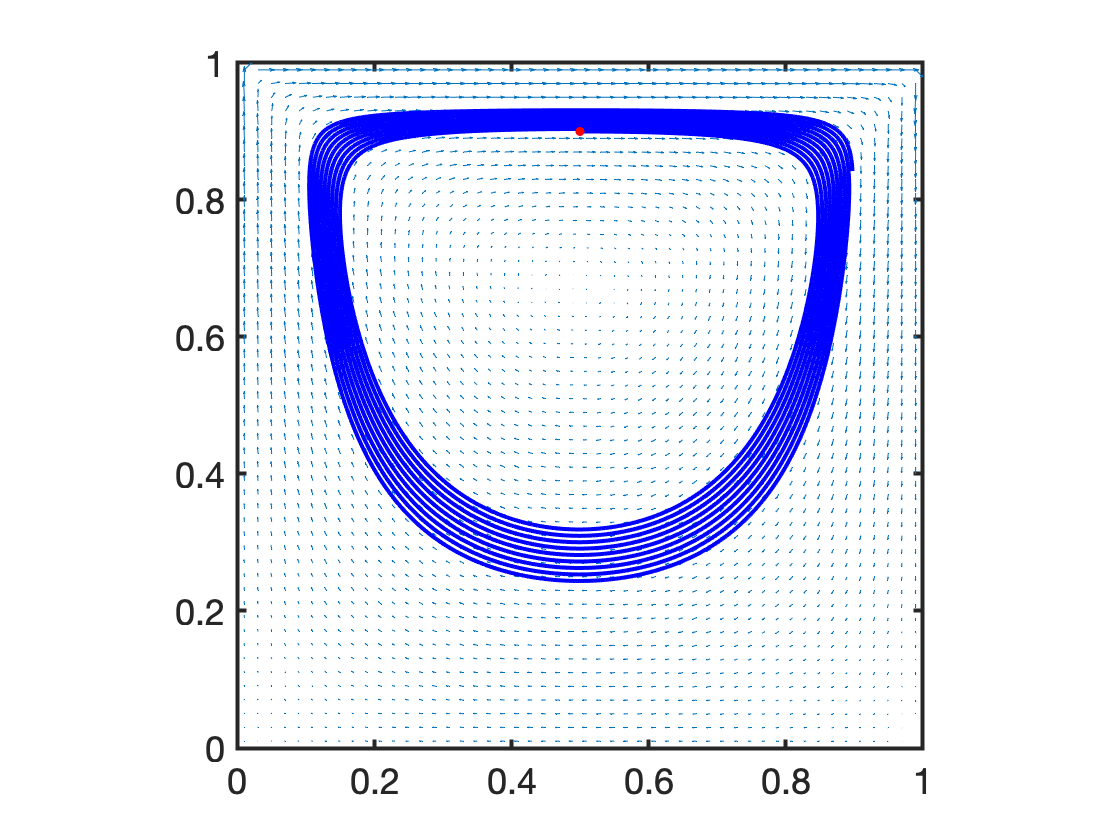

streamline(Xc,Yc,VXc,VYc,0.5,0.9), hold on
plot(0.5,.9,'r.')

A better option is to use the streamfunction that will be discussed in lecture today. Looks like this is the only good way to plot streamlines in circulating flows.

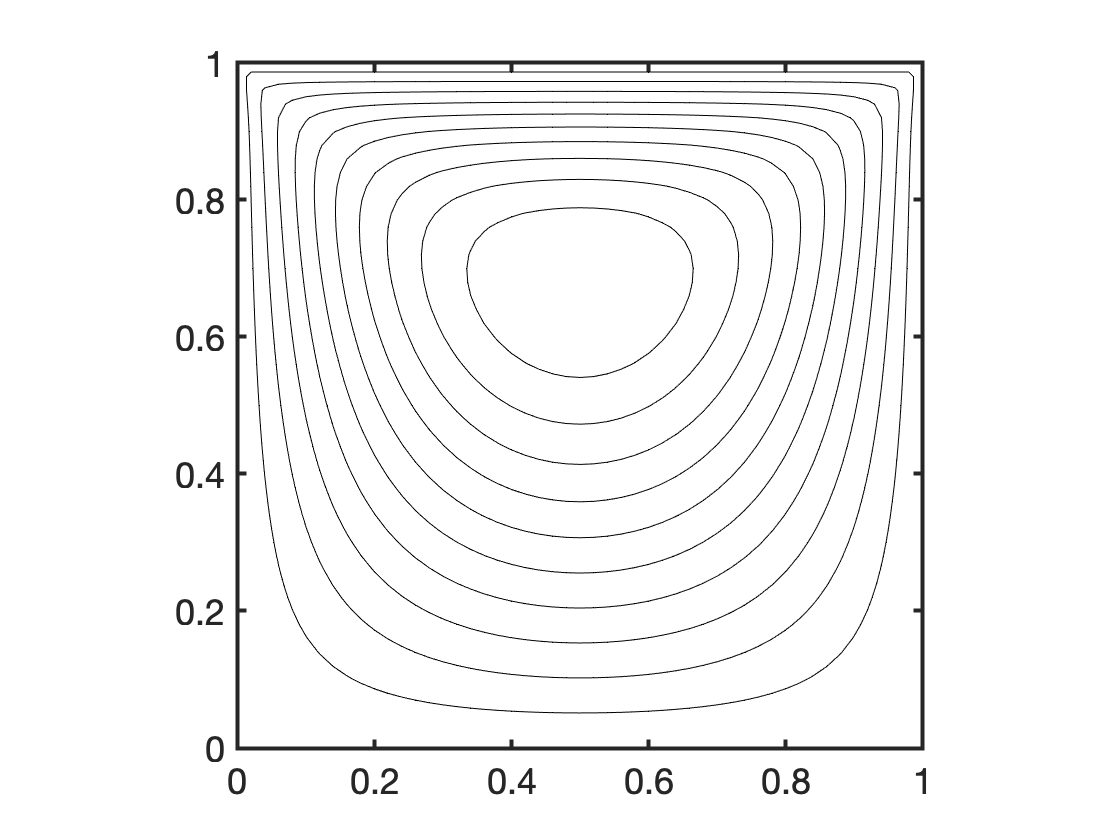

%% Plot solution
[Xp,Yp] = meshgrid(Grid.x.xc,Grid.y.yc);
figure
contour(Xp,Yp,PSI,10,'k')
axis square